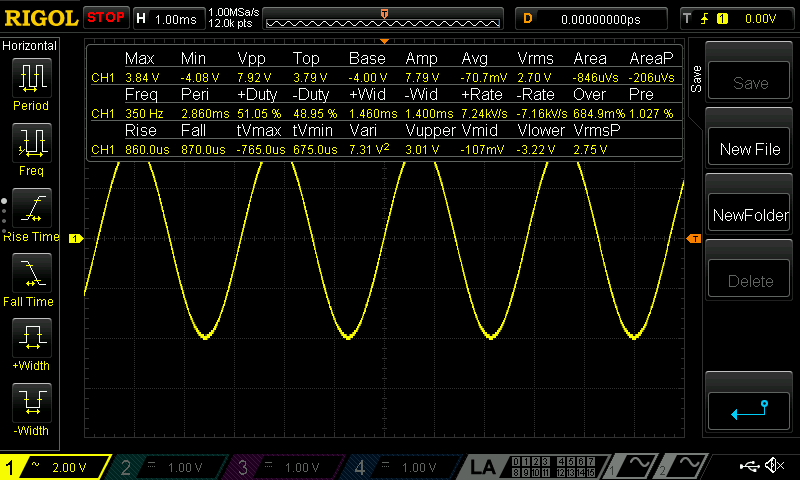

## Codigo de señal de senoidal

Este practica se hizo con base a los conocimientos impartidos por el profesor y otros medios, con la cual se busco crear un codigo en el lenguaje de programación Matlab que nos cumpliera ciertos requerimientos, del mismo modo se usaron diferentes fuentes para realizar el codigo como YouTube, Matlab y Chatgpt los cuales fueron de suma importancias para el estudiante. 

Por otro lado se registraron valores por medio de este codigo, en los cuales se logro graficar la forma de onda (senoidal) y su espectro, del mismo modo otros valor como valorrms, frecuencia, periodo y valor medio en los cuales se puede observar cierta similitud respecto a lo mostrado en el osciloscopio por lo tanto se puede inferir que la practica fue un exito.

- Con base a la fracuencia podemos observar que en el osciloscopio nos arroja un valor de 350Hz y por parte del codigo 333.333Hz y eso nos da un margen de error de 4.762%.

- En segundo lugar se observo una diferencia del -4.895% con base al periodo del osciloscopio y el codigo.

- En tercer lugar se observo un valor similar, tanto del osciloscopio y el codigo al respecto del valor rms.

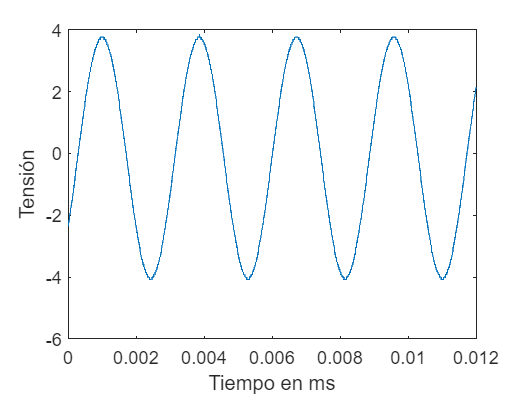

datos = readmatrix("NewFile6.csv");
tiempo = datos(:, 1);
tension = datos(:, 2);

t = 12*1e-3;
ti= 12000/t; %velocidad de muestreo
in = 1/ti;
tiempo_muestreo = tiempo*in;

plot(tiempo_muestreo, tension);
xlabel('Tiempo en ms');
ylabel('Tensión');

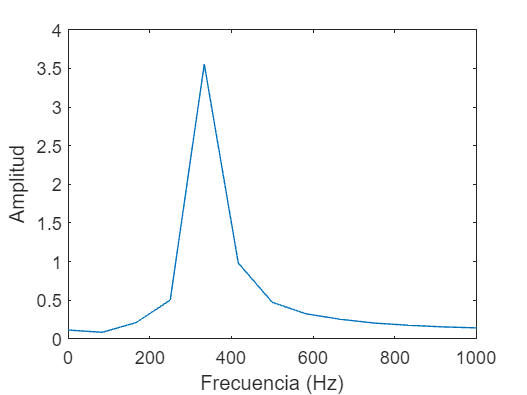


%Calculamos los datos requeridos

N = length(tension);
T = tiempo_muestreo(2) - tiempo_muestreo(1);
Fs = 1 / T;
f = Fs * (0:(N/2))/N;
Y = fft(tension);
P2 = abs(Y/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1);

plot(f, P1);
xlabel('Frecuencia (Hz)');
ylabel('Amplitud');
xlim([0 1000])


[valor_pico, indice_pico] = max(P1);
frecuencia_fundamental = f(indice_pico);

%Calculamos el periodo de la señal
periodo = 1/frecuencia_fundamental; 

%Calculamos el valor medio de la señal
valor_medio = mean(tension);

%Calculamos el valor RMS de la señal
valor_rms = sqrt(mean(tension.^2));

%Mostramos los resultados
fprintf('Frecuencia fundamental: %.2f Hz\n', frecuencia_fundamental);

Frecuencia fundamental: 333.33 Hz


fprintf('Periodo de la señal: %.4f m\n', periodo);

Periodo de la señal: 0.0030 ms


fprintf('Valor medio de la señal: %.2f V\n', valor_medio);

Valor medio de la señal: -0.11 V


fprintf('Valor RMS de la señal: %.2f V\n', valor_rms);

Valor RMS de la señal: 2.70 V
